## Instructions

- Run each cell in order

- Modify the lines that have **green comments**

- This notebook by default assumes that: time/samples are rows and channels are columns

- Feel free to try more involved preprocessing steps, but make sure to assign your results back to the appropriate variables

## Preprocessing

### Step 1. Load the dataset

clearvars
load("datasets\training_dataset.mat")

### Step 2. Visualize the raw data

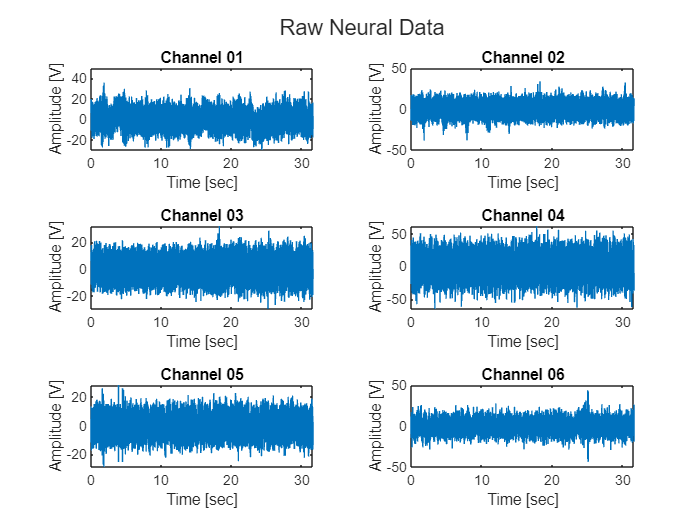

[num_samples, num_chans] = size(experiment_data.raw_neural_data);
timestamps = (1:num_samples)/experiment_data.sample_rate;

figure
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    nexttile
    plot(timestamps, experiment_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [V]')
end
title(fig_raw, 'Raw Neural Data')

### Step 3. Filter the data

The current cutoff frequencies (10 Hz and 20 Hz) for the passband filter have been chosen at random. Play around with the values of the cutoff frequecies until you find a suitable range for the passband filter. 

tic
passband = [20 30]; % passband frequency of filter in Hz (CHANGE THESE VALUES)
filtered_data = bandpass( double(experiment_data.raw_neural_data), ...
    passband, ...
    experiment_data.sample_rate);
toc

Elapsed time is 43.787954 seconds.


### Step 3. Visualize the filtered data

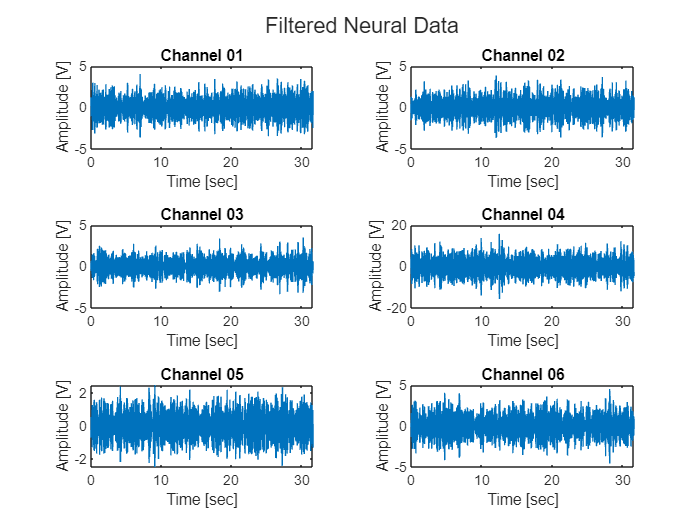

figure
fig_filt = tiledlayout("flow");
for i=1:num_chans
    nexttile
    plot(timestamps, filtered_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [V]')
end
title(fig_filt, 'Filtered Neural Data')

## Feature Extraction: Spike Trains

### Step 1. Use thresholding to detect spikes

Do literature review to find suitable formulas for the threshold you'll use for spike detection. You will need to specify on threshold for each channel

spike_threshold = 3.5*std(filtered_data) % thresholding formula (CHANGE THIS FORMULA)

spike_threshold =     3.6544    3.5945    2.9229   13.0682    2.4818    4.0499


### Step 2. Generate spike trains

Use your threshold to detect spikes. In this case the default code uses negative thresholding to detect spikes.

The result of your detection formula shoud be a `6xN` matrix. 

Each column of the `spike_train` matrix is a logical array with a value of `1` where a spike is detected, and `0` everywhere else.

spike_trains = diff(filtered_data < -1*spike_threshold) == 1; % spike detection formula (CHANGE THIS FORMULA)

### Step 3. Visualize the Spike Trains in a Raster Plot

The raster plot below shows the spikes detected in each channel contrasted with the kinematics.

Ideally, you'd want to see a concentration of spikes near the peaks of the kinematics, and no spikes during the resting periods.

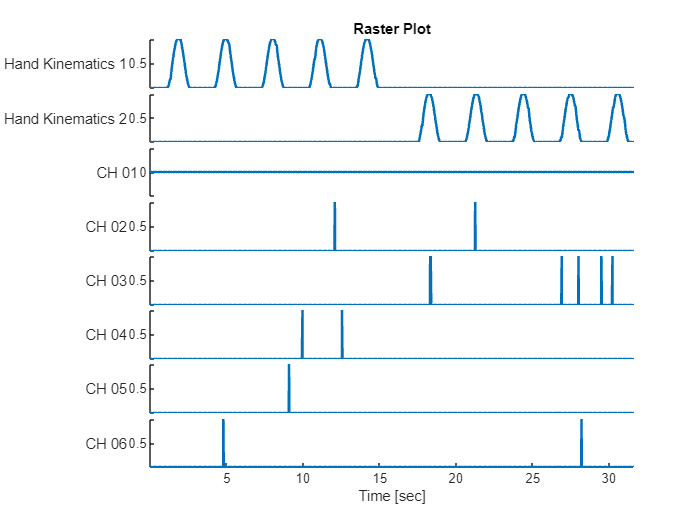

figure
fig_raster = stackedplot(timestamps(1:length(spike_trains)),[experiment_data.hand_kinematics(1:length(spike_trains),:), spike_trains], LineWidth=1.5);
fig_raster.DisplayLabels = ["Hand Kinematics 1", "Hand Kinematics 2", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
fig_raster.XLabel = "Time [sec]";
fig_raster.Title = "Raster Plot";

### Step 3. Plot the Action Potentials from the Spike Trains

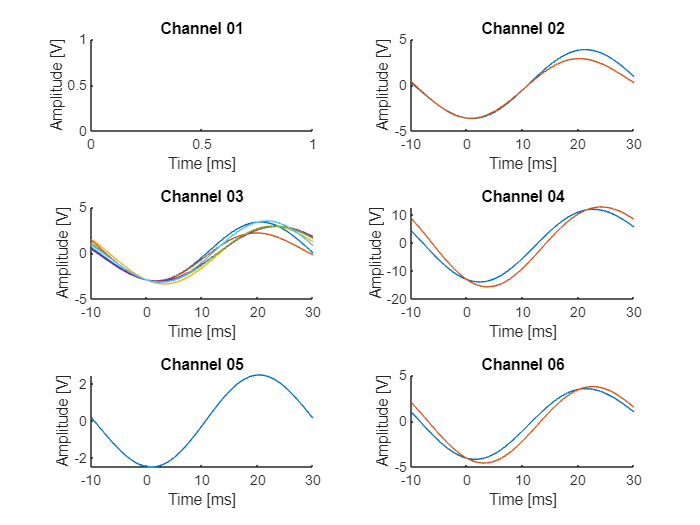

figure
fig_spike_train = tiledlayout('flow');
spike_before = 10e-3 * experiment_data.sample_rate; % Time [s] before the action potential crosses the threshold (CHANNGE THIS VALUE)
spike_after = 30e-3 * experiment_data.sample_rate;  % Time [s] after the action potential crosses the threshold (CHANGE THIS VALUE)
spike_duration = (-spike_before:spike_after)/experiment_data.sample_rate * 1e3;
for chan=1:num_chans
    nexttile
    spike_idxs = find(spike_trains(:, chan))';
    hold on
    for i = spike_idxs
        if i-spike_before < 1; continue; end
        if i+spike_after > num_samples; continue; end
        plot(spike_duration,filtered_data(i-spike_before:i+spike_after, chan))
    end
    hold off
    xlabel("Time [ms]")
    ylabel("Amplitude [V]")
    title(sprintf("Channel %02d", chan))
end

### Step N. Find the spike rate of each channel